# **Question 1(c)**

#### **plot of sigma P**

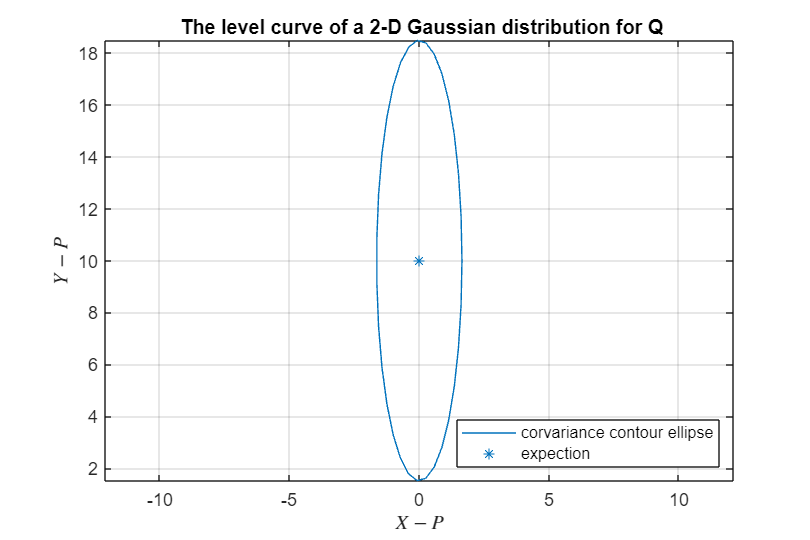

clear all
clc
mu_p=[0;10];sigma_p=[0.3 0;0 8];A=[1 0.5;0 1];b=zeros(2,1);

%Call your function.
xy_p = sigmaEllipse2D(mu_p, sigma_p);

%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_p(1,:), xy_p(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{P}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{P}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for Q')
grid on ;
plot(mu_p(1), mu_p(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

#### plot of sigma P

[mu_z, sigma_z] = affineGaussianTransform(mu_p, sigma_p, A, b)

mu_z =      5
    10


sigma_z =     2.3000    4.0000
    4.0000    8.0000


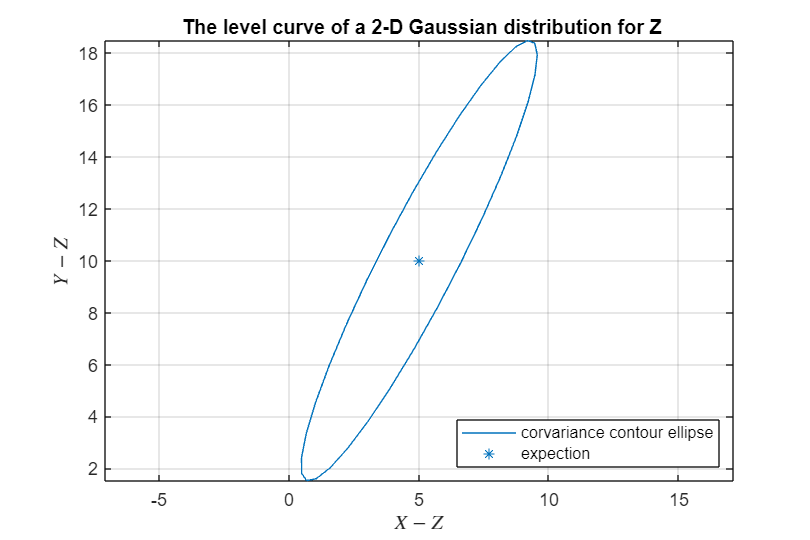

xy_z = sigmaEllipse2D(mu_z, sigma_z);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_z(1,:), xy_z(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{Z}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{Z}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for Z')
grid on ;
plot(mu_z(1), mu_z(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

# Question2(a)


mu_x2=0;sigma_x2=2;
A2=3;b2=0;f=@(x)(3*x);N=10000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18



[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = 0.0113

sigma_z3 = 18.1861

y_z3 =    -3.4320    5.8021    6.1960   -3.6727    5.1232    4.3683   -7.0360   -3.3097    4.5357    5.3342    7.6237    2.5903   -9.4023    2.8572    0.9618    7.3103    3.2401   -2.0413    5.6088   -9.9252   -2.0017    8.7418   -0.0764   -1.6595   -1.1009   -3.4633    3.7162   -5.2530   -6.7956    6.1667   -5.6367    7.1676   -4.7305   -0.1830    2.0985    1.3229   -0.6549    1.0805    2.2872   -1.3297   -1.0517    6.3422    2.7336   -3.0265    2.9362   -0.8679   -0.1918   -0.3241    3.2271    0.4185


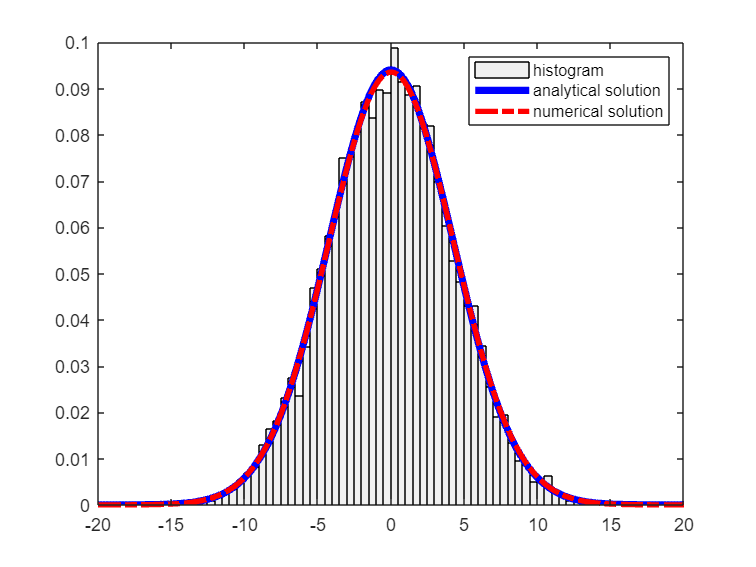

figure()
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')

# Question2(b)

f2=@(x)(x^3);N=100000;
[mu_z4, sigma_z4, y_z4] = approxGaussianTransform(mu_x2, sigma_x2, f2, N)

mu_z4 = 0.0079

sigma_z4 = 116.0812

y_z4 =     0.2128   -2.7605    3.1741   -0.0628    1.4408   -1.7825    0.5787   -5.8031  -13.5364    0.2465    0.0006    0.0957    1.7319    0.0001    0.0052  -47.8550   -0.0240   -7.8115   72.2487    0.6335   14.2461    4.9584   -0.4373    0.0448   13.2746   -0.5822   -2.0029   -0.6481    2.1306    0.0092    0.1410   -5.3849    0.0000    0.1603    0.1562    0.9609   26.1387   -0.7782   -5.0803   -9.3178    0.9883   -1.9224  -37.6175   -6.1352    0.3179    1.0579   -0.3102   -0.0057    2.8144  -32.5887


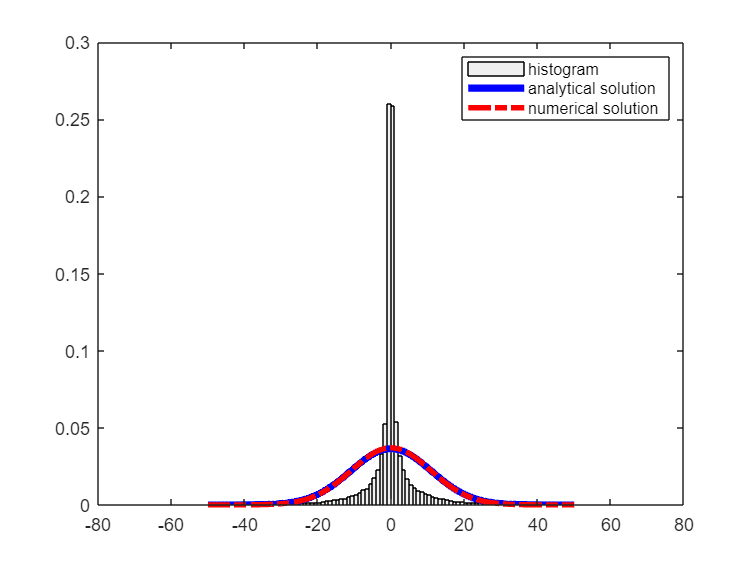

figure()
histogram(y_z4,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x1=[-50:0.1:50];
xlim([-80,80])
y=normpdf(x1,0,sqrt(120));
plot(x1,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x1,mu_z4,sqrt(sigma_z4));
plot(x1,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
%nonlinear transform, not a Gaussian
hold off

# Question3

# P(y)

clear all
N=100000;
H21=@(x)(4*x);%linear function
a=10;b=20;
x31=[-200:1:200];
%assume sigma_r^2=25
X_uni=a+(b-a)*rand(1,N)%get samples using uniform distribution

X_uni =    13.8807   17.0191   19.0793   13.4553   16.9601   16.7838   11.8559   15.4377   15.0903   14.3550   18.5085   13.0192   11.0771   14.8816   18.2485   18.6978   10.8495   14.7230   18.1807   14.3597   12.4821   18.6016   14.1147   17.6167   12.2174   11.0316   16.3841   13.1111   19.0047   10.8086   13.3021   18.5357   18.1755   10.9130   13.2588   14.8277   10.8949   16.6770   17.8194   14.6891   11.5200   19.7842   16.8157   17.2619   17.5644   16.3752   17.3663   17.2488   16.7060   11.7433


r=mvnrnd(0, 25,N)'%get samples using normal distribution

r =    -0.1444    4.3577    2.0064   -3.2380   -6.8563   -7.7734   -0.9928   -3.6690    3.1148   -6.0717   -2.5879   -5.7462   -1.5435   -4.3020   -7.2695    0.9528   -2.2299   -2.5181    6.9626    0.7467    0.2742   -6.6521    1.0821    1.8832    4.5484   -0.0410    7.7101   -0.4720    6.6299    0.4805   -3.7682    0.9090   -2.8187    3.9397   -7.2178   -2.5267    0.3292    6.4649   -0.3553    0.1075    2.0838    2.6115   -3.4408    3.3152   -9.0809   -4.9499   -2.1889   -3.0938   -6.6792    3.6202


% X_uni=unifpdf(x31,-20,20)
ys_3111=[];
for i=1:N
    ys_3111=[ys_3111,H21(X_uni(:,i))];%if it is uniform
end
ys31=[1 1]*[ys_3111;r];
histogram(ys31,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
% figure()
% plot(normys31)
hold on
y=[0:0.1:100]

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


func=-(erf(8-y/5)+erf((y-80)/5))/(80)

func =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


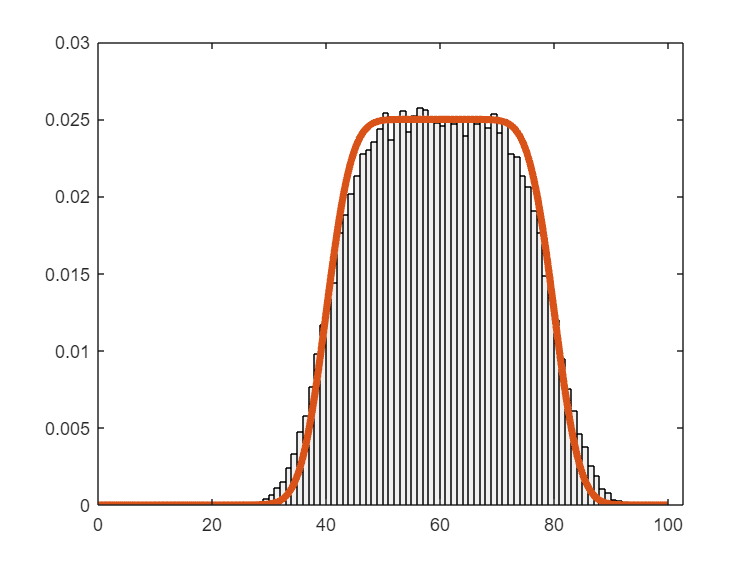

plot(y,func,'LineWidth',4)
hold off

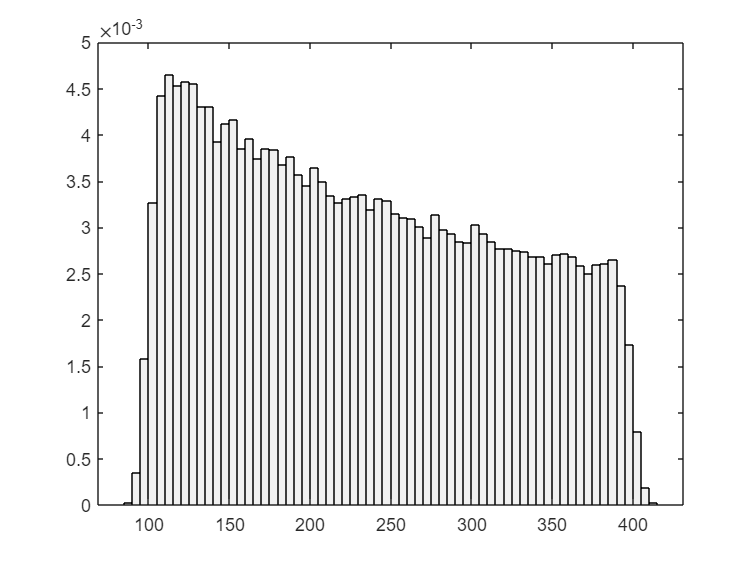

%Integrate[1/10*(1/(sqrt(2*pi*5^2)))*exp(-(y-x^2)^2/2*5^2),{x,10,20}]
H31=@(x)(x^2);%nonlinear function
ys_3222=[];
for i=1:N
    ys_3222=[ys_3222,H31(X_uni(:,i))];%if it is uniform
end
ys32=[1 1]*[ys_3222;r];
histogram(ys32,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold off

X_normal=mvnrnd(0, 25,N)'

X_normal =    -7.4293    9.9341    6.2751    5.9128  -10.3446   -0.4814   -1.3634    7.3413    7.1497   -7.7406    4.8540    2.5376   -3.9463   -2.3392  -10.0471   -0.2897   -0.6112    9.0359   -1.6071   -5.7155   -5.4103    1.4518   -2.0805    1.7090    2.6271   -4.0524    7.7615   11.4732    5.8139   -0.4243    4.7926   -0.7405    5.1630    1.0711    0.2191    1.8836   -5.5707   -3.7458   -2.3903    1.5581    2.6945    5.2092    1.0470    7.3344    1.2168   -1.2108   -6.8435    7.4334    0.7425   -3.7587


ys_3333=[];
for i=1:N
    ys_3333=[ys_3333,H21(X_normal(:,i))];%if it is uniform
end
ys33=[1 1]*[ys_3333;r];
figure()
histogram(ys33,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normal3=[-100:0.1:100];
y=normpdf(x_normal3,0,sqrt(425))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


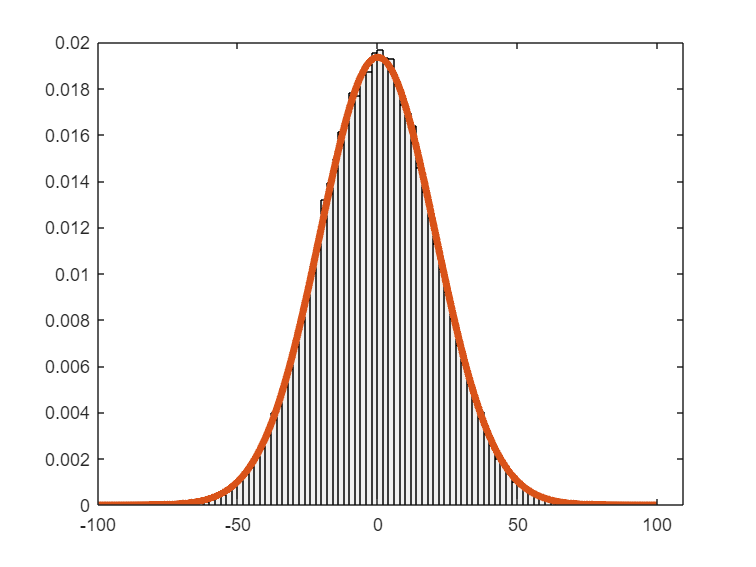

plot(x_normal3,y,'LineWidth',4)
hold off

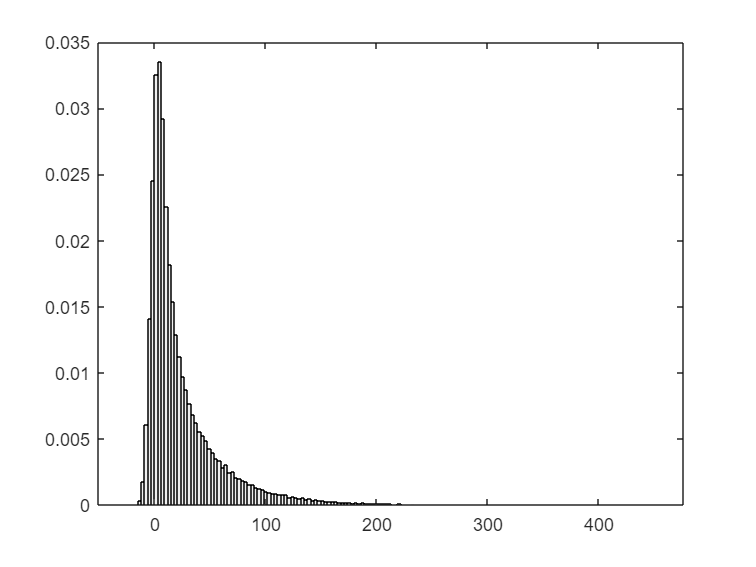

ys_3444=[];
for i=1:N
    ys_3444=[ys_3444,H31(X_normal(:,i))];%if it is uniform
end
ys34=[1 1]*[ys_3444;r];
histogram(ys34,'Normalization','pdf','FaceColor',[.9 .9 .9]) 

# P(y|x)

%%%%%%uniform linear
X_rand=a+(b-a)*rand;
y_31pyx=r+H21(X_rand);
figure()
histogram(y_31pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normalyx1=[0:0.1:95];
y=normpdf(x_normalyx1,H21(X_rand),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


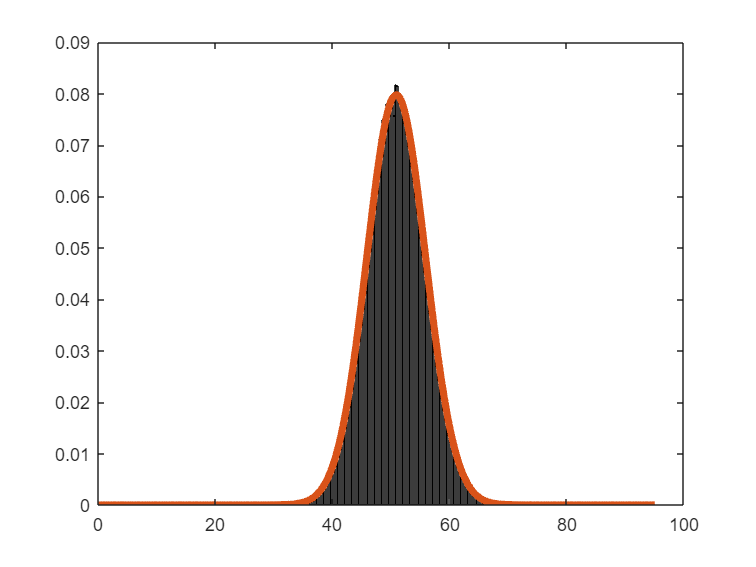

plot(x_normalyx1,y,'LineWidth',4)
hold off

%%%%%%uniform nonlinear
y_32pyx=r+H31(X_rand);
figure()
histogram(y_32pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx2=[100:0.1:250];
y=normpdf(x_normalyx2,H31(X_rand),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


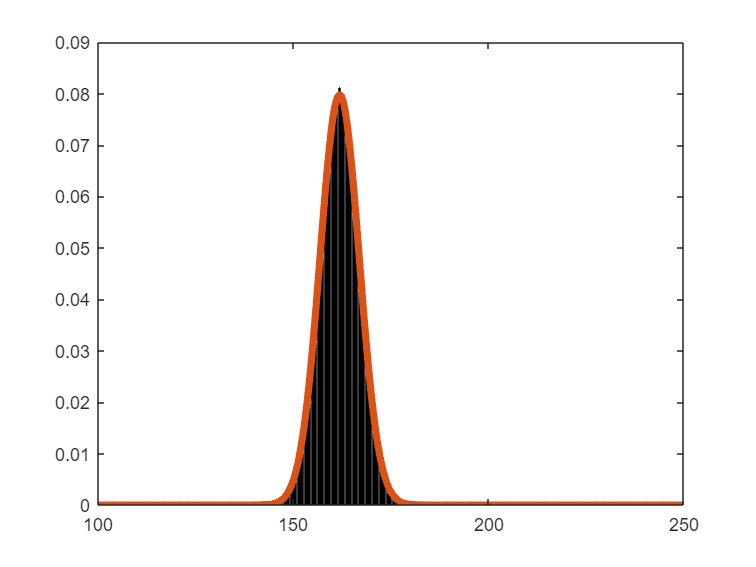

hold on
plot(x_normalyx2,y,'LineWidth',4)
hold off

X_randn=mvnrnd(0, 25,1);

%%%%%%guassian linear
y_33pyx=r+H21(X_randn);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx3=[-50:0.1:50];
hold on
y=normpdf(x_normalyx3,H21(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


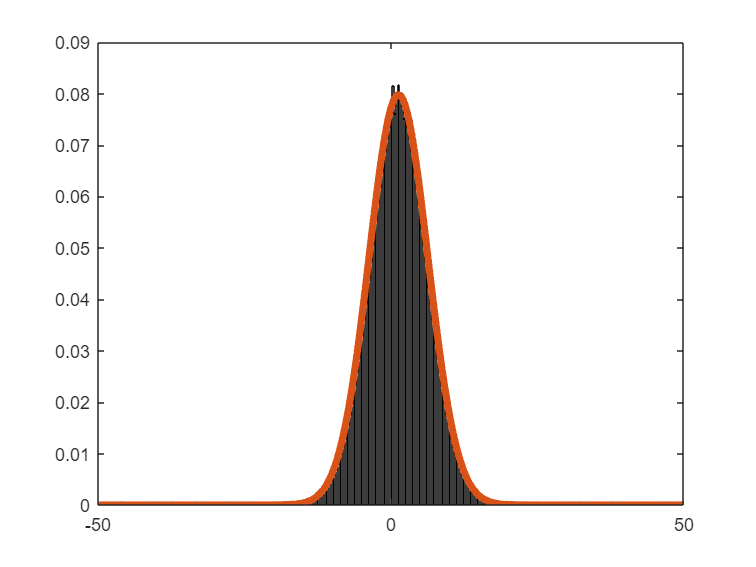

plot(x_normalyx3,y,'LineWidth',4)
hold off

%%%%%%guassian nonlinear
y_33pyx=r+H31(X_randn);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx4=[-50:0.1:50];

hold on
y=normpdf(x_normalyx4,H31(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


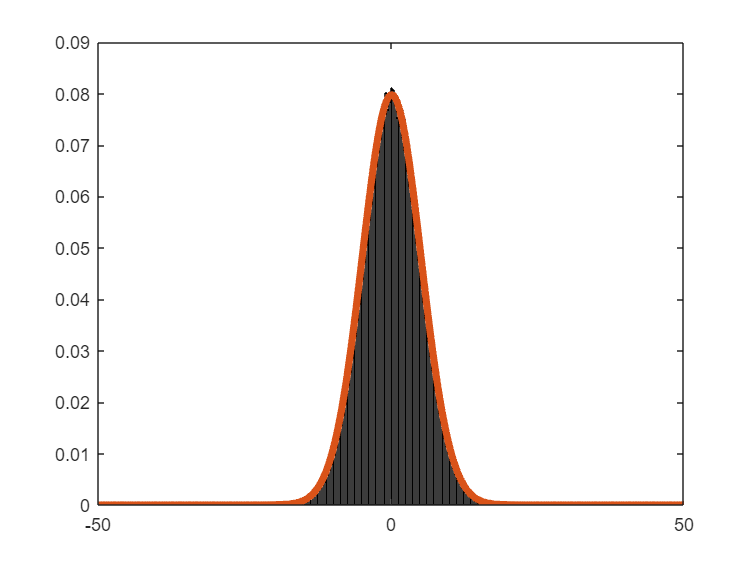

plot(x_normalyx4,y,'LineWidth',4)
hold off

# Question4

clear all
sigma41=0.5^2;
N=100000;
x41=[-4:0.1:4];
y41=0.5*normpdf(x41,-1,sqrt(sigma41))+0.5*normpdf(x41,1,sqrt(sigma41));
figure()
plot(x41,y41,'LineWidth',4);
hold on
w=(mvnrnd(0,sigma41,N))'

w =     1.1226   -0.0872   -0.3249    0.4036    0.9322   -0.1820   -0.5147   -0.3547    0.3324   -0.2304    0.7454   -0.9651    0.5224   -0.1783    0.5955    0.0093   -0.6350   -0.4936    1.0707   -0.6232   -0.6650    0.2326    0.3465    0.2782    1.2899    0.4577    0.0952    0.5103    0.6128   -0.9185   -0.7802   -0.8191   -0.0980    0.5063    0.4277    0.4093   -0.1106    0.3065    0.3834    0.7189   -0.5936   -1.1884    0.1938    0.0707    0.4270    0.0918    0.1311    0.2781   -0.1406   -0.2309


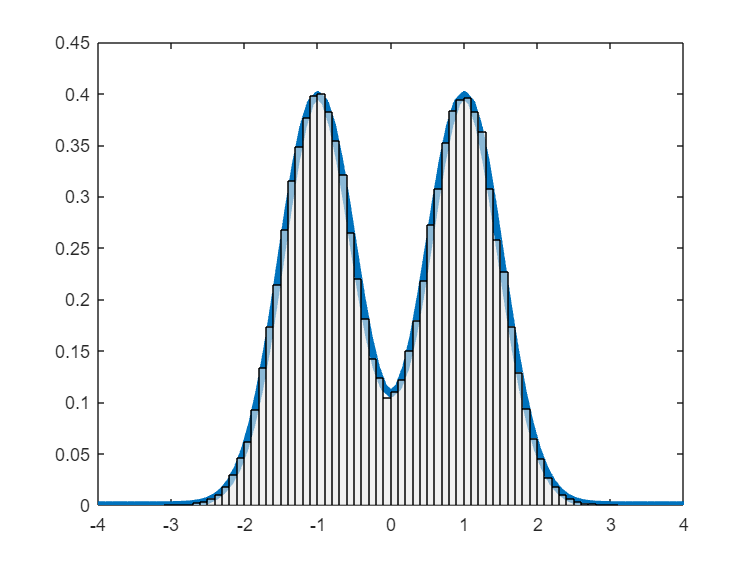

y42=[];
for i=1:N
    random_bit = randi([0, 1], 1, 1);
    if random_bit == 0
        theta = -1;
        y42=[y42 theta+w(i)];
    else
        theta = 1;
        y42=[y42 theta+w(i)];
    end
end
histogram(y42,'Normalization','pdf','FaceColor',[.9 .9 .9]) 

# function

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.


%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end
phi=linspace(0,2*pi,npoints);
xy=zeros(2,npoints);
n=0;
for i=1:npoints
    xy(:,i)=mu+level*sqrtm(Sigma)*[cos(phi(:,i));sin(phi(:,i))];
end
%Your code here
%disp(size(xy,2))
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y] = affineGaussianTransform(mu_x, Sigma_x, A, b)
%affineTransformGauss calculates the mean and covariance of y, the 
%transformed variable, exactly when the function, f, is defined as 
%y = f(x) = Ax + b, where A is a matrix, b is a vector of the same 
%dimensions as y, and x is a Gaussian random variable.
%
%Input
%   MU_X        [n x 1] Expected value of x.
%   SIGMA_X     [n x n] Covariance of x.
%   A           [m x n] Linear transform matrix.
%   B           [m x 1] Constant part of the affine transformation.
%
%Output
%   MU_Y        [m x 1] Expected value of y.
%   SIGMA_Y     [m x m] Covariance of y.

%Your code here
    mu_y=A*mu_x+b;%mu_z=E{AX+BY}=A*mu_x+B*mu_y
    Sigma_y=A*Sigma_x*A';%Sigma_z=Cov{AX+BY}=Cov{Ax}+Cov{By}
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y, y_s] = approxGaussianTransform(mu_x, Sigma_x, f, N)
%approxGaussianTransform takes a Gaussian density and a transformation 
%function and calculates the mean and covariance of the transformed density.
%
%Inputs
%   MU_X        [m x 1] Expected value of x.
%   SIGMA_X     [m x m] Covariance of x.
%   F           [Function handle] Function which maps a [m x 1] dimensional
%               vector into another vector of size [n x 1].
%   N           Number of samples to draw. Default = 5000.
%
%Output
%   MU_Y        [n x 1] Approximated mean of y.
%   SIGMA_Y     [n x n] Approximated covariance of y.
%   ys          [n x N] Samples propagated through f


if nargin < 4
    N = 5000;
end

%Your code here
X = mvnrnd(mu_x, Sigma_x,N)';
% disp(size(X,1))
mu=zeros(size(mu_x,1),1);
y_s=[];
for i=1:N
    y_s=[y_s,f(X(:,i))];
end
mu_y=mean(y_s,2);
Sigma_y=(y_s-mu_y)*(y_s-mu_y)'/(N-1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu, Sigma] = jointGaussian(mu_x, sigma2_x, sigma2_r)
%jointGaussian calculates the joint Gaussian density as defined
%in problem 1.3a. 
%
%Input
%   MU_X        Expected value of x
%   SIGMA2_X    Covariance of x
%   SIGMA2_R    Covariance of the noise r
%
%Output
%   MU          Mean of joint density 
%   SIGMA       Covariance of joint density
A=[1 0;1 1];b=zeros(2,1);
mu_x=[mu_x,0]';
Sigma_x=[sigma2_x,0;0,sigma2_r];
[mu, Sigma] = affineGaussianTransform(mu_x, Sigma_x, A, b);
%Your code here
end